close all;
clearvars;
clc;

## LOAD NN

load network.mat;

## READ FILE

[file,path] = uigetfile({'*.jpg'; '*.png'}, 'PILIH GAMBAR');

## PENG HISTO

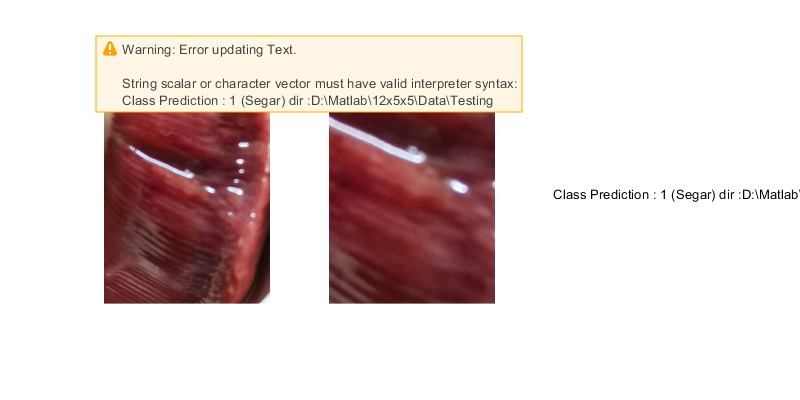

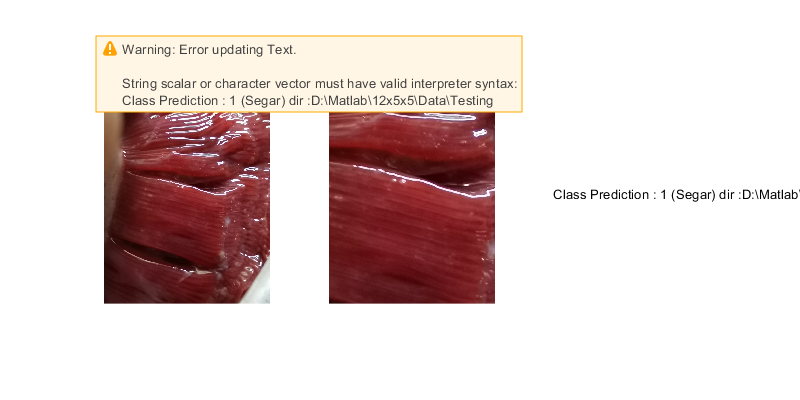

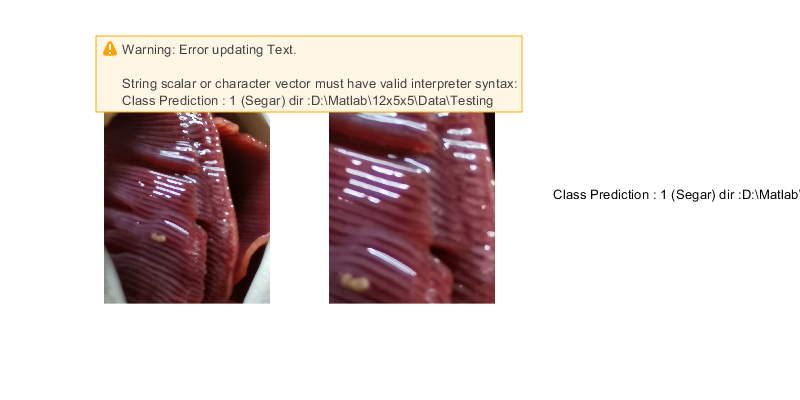

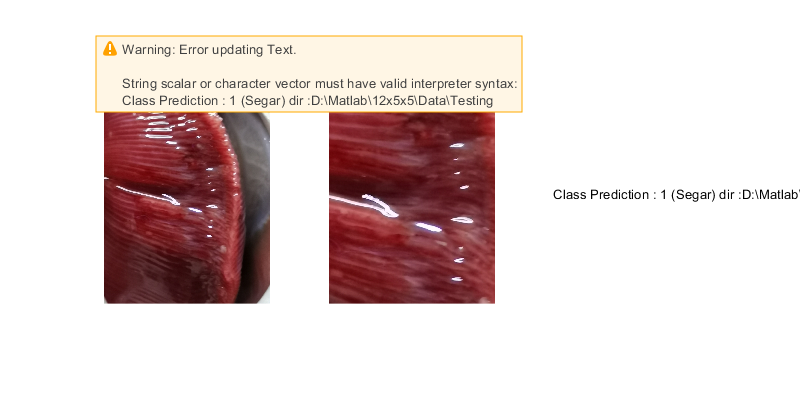

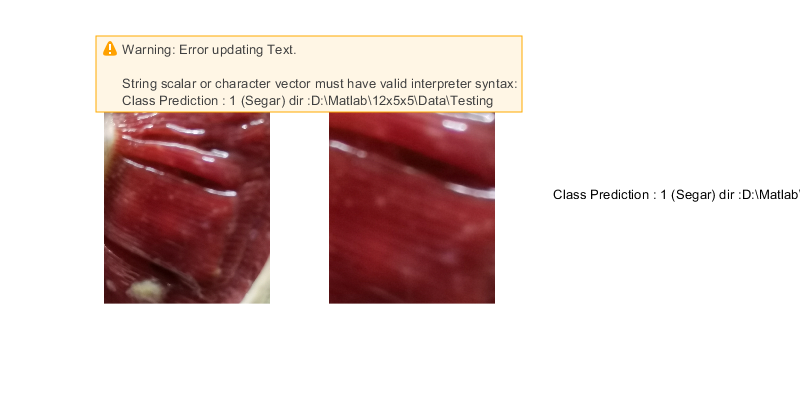

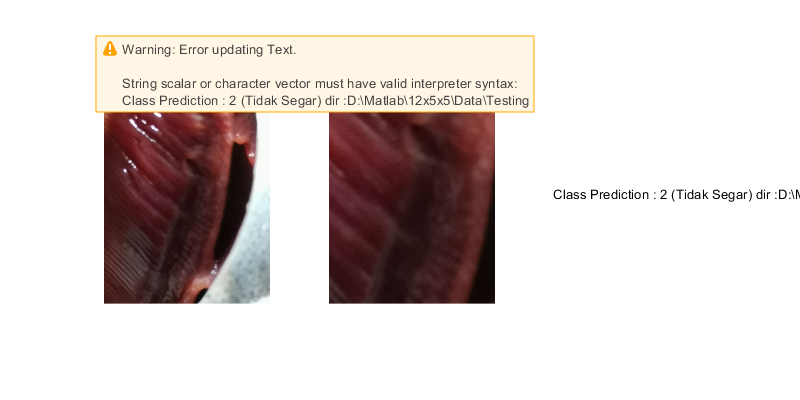

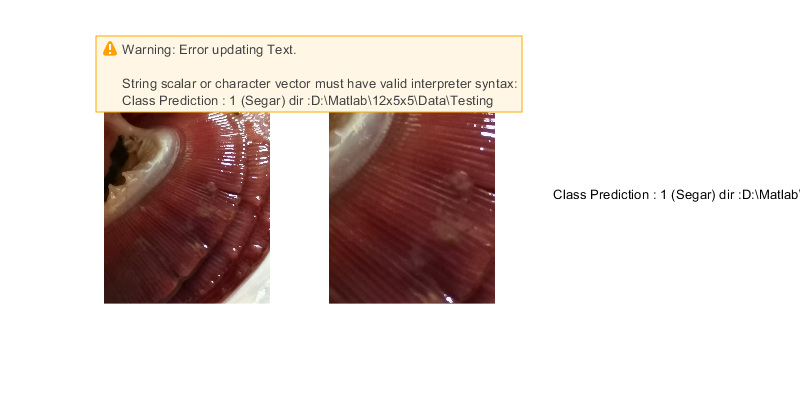

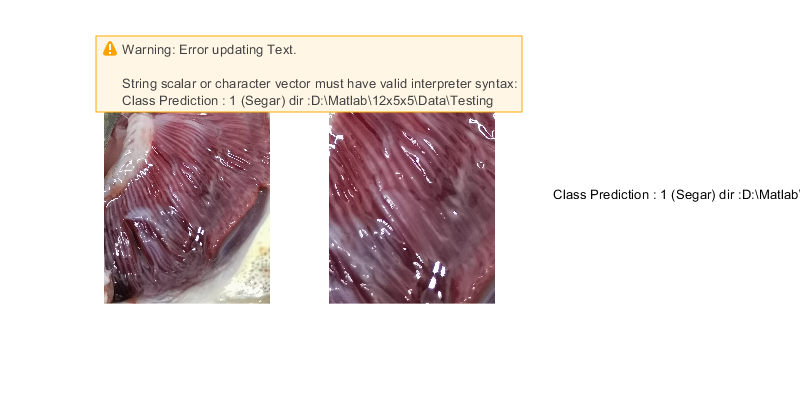

I=imread([path, file]);
dir = uigetdir('default','Pilih Folder Data Testing');
fig = uifigure;
d = uiprogressdlg(fig,'Title','Processing...',...
    'Indeterminate','on');
drawnow
imds = imageDatastore(dir, 'IncludeSubfolders', true);
images_num = size(imds.Files,1);
for num = 1:images_num
    I = readimage(imds,num);
    [filePath, fileName, fileExt] = fileparts(imds.Files{num});
    class = str2double(extractBefore(fileName,"_"));
    [X,Y]=size(I(:,:,1));
    
    cX = floor(X/2);
    cY = floor(Y/2);
    
    crop = I(cX-floor(X/4):cX+floor(X/4), cY-floor(Y/4) : cY+floor(Y/4),:);
    crop_hsv=rgb2hsv(crop);
    [N,M,L]=size(crop);
    Hk = 12; Ck = 4; Lk = 4;
    HCL_Histo(1:Hk, 1:Ck+1, 1:Lk) = 0;
    gamma = 1;
    Q = exp(gamma/100.0);
    Ldiv = ceil((2*Q-1.0)*255/(2.0*Lk));
    Cdiv = round(2*255*Q/(3.0*Ck));
    Hdiv = 30;
    for n=1:N
        for m=1:M
            b=double(crop(n,m,3)); g=double(crop(n,m,2)); r=double(crop(n,m,1));
            
            Max = max(r,max(g,b));
            Min = min(r,min(g,b));
            if Max==0
                Q=1.0;
            else
                Q = exp((Min*gamma)/(Max*100.0));
            end
            L = floor((Q*Max+(Q-1.0)*Min)/(2.0*Ldiv));
            rg = (r-g); gb = (g-b);
            C = (abs(b-r) + abs(rg) + abs(gb))*Q/(3.0);
            if C<=5
                C=0;
            else
                C = 1 + floor((C-5)/Cdiv);
            end
            H = atan(gb/rg);
            if (C==0)
                H=0.0;
            elseif (rg>=0&&gb>=0)
                H=2*H/3;
            elseif ((rg>=0)&&gb<0)
                H=4*H/3;
            elseif (rg<0&&gb>=0)
                H=pi+4*H/3;
            elseif ((rg<0)&&gb<0)
                H=2*H/3-pi;
            end
            H = H*(180/pi)+Hdiv/2;
            if H<0
                H=floor((360+H)/(Hdiv));
            else
                H = floor(H/(Hdiv));
            end
            HCL_Histo(H+1,C+1,L+1) = HCL_Histo(H+1, C+1, L+1)+1;
        end
    end
    HCL_Histo = (100*HCL_Histo/(N*M));
    HCL_Histo_1D=reshape(HCL_Histo,[1,240]);
    
    YPred = classify(network,HCL_Histo_1D);
    if(uint8(YPred) == 1)
        strPred = 'Segar';
    elseif(uint8(YPred) == 2)
        strPred = 'Tidak Segar';
    %elseif(uint8(YPred) == 3)
        
    end
    
    figure('Name', 'Result', 'Position', [400 400 800 400])
    subplot(1,3,1);
    imshow(I);
    title('Original');
    
    subplot(1,3,2);
    imshow(crop);
    title('Cropped');
    
    subplot(1,3,3);
    text(0,0.5,['Class Prediction : ', char(YPred),' (', strPred, ')',' dir :', dir]);
    set(gca,'Visible','off')
end

## CLASSIFY

YPred = classify(network,HCL_Histo_1D);
if(uint8(YPred) == 1)
    strPred = 'Segar';
elseif(uint8(YPred) == 2)
    strPred = 'Tidak Segar';
%elseif(uint8(YPred) == 3)
    
end

## DISPLAY OUTPUT

figure('Name', 'Result', 'Position', [400 400 800 400])
subplot(1,3,1);
imshow(I);
title('Original');

subplot(1,3,2);
imshow(crop);
title('Cropped');

subplot(1,3,3);
text(0,0.5,['Class Prediction : ', char(YPred),' (', strPred, ')']);
set(gca,'Visible','off')